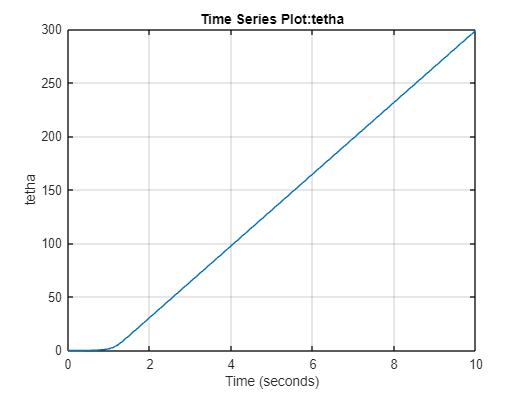

yout = out.simout;
plot (yout);
grid on

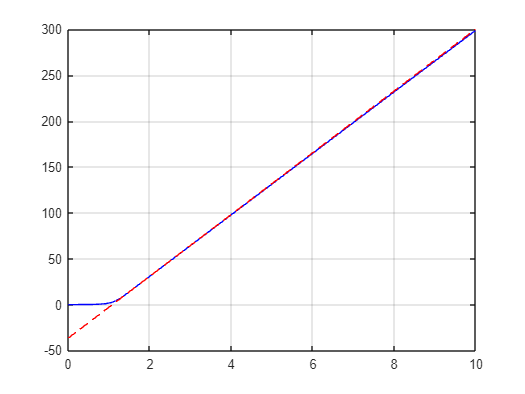

signal = yout.Data(:, 1);
time = yout.Time;
dt = diff(time); 
dsignal = diff(signal) ./ dt; 

[max_slope, idx] = max(dsignal);  

x_tangent = time(idx);             
y_tangent = signal(idx);

y = max_slope * (time - x_tangent) + y_tangent;

plot(time, signal, 'b');
hold on;
plot(time, y, 'r--');
ylim([-50 300]);
grid on

L_Plus_T = (-y_tangent / max_slope) + x_tangent

L_Plus_T = 1.0846

K = (max_slope * (- x_tangent) + y_tangent) / L_Plus_T*(-1)

K = 33.6495

signal_at_L_Plus_T = interp1(time, signal, L_Plus_T)

signal_at_L_Plus_T = 2.6164

T = signal_at_L_Plus_T*exp(1)/K

T = 0.2114

L = L_Plus_T - T

L = 0.8733